# Numerical Integration Using Simpson Method

*Pouria Motahhari, Chemical and Petroleum Engineering Department, Fall 2022*

Numerical integration is a fundamental tool in mathematics, engineering, and scientific computing, enabling the approximation of definite integrals for a wide range of functions. This document explores the implementation of numerical integration using MATLAB, with a specific focus on the Trapezoidal Rule. The code provided calculates the integral of a user-defined function over a specified interval and offers a comparison with the analytical integral value. Whether you are a student studying numerical methods or a professional seeking to apply numerical integration in practical applications, this document provides a clear explanation of the MATLAB code's functionality and its potential for customization to suit your integration needs.

Simpson's integration method, attributed to mathematician Thomas Simpson, is a widely utilized numerical technique for approximating definite integrals. It partitions the integration interval into small segments and employs quadratic approximations within each interval. By doing so, it provides a more accurate estimate of the integral's value compared to simpler methods like the trapezoidal rule. This method is invaluable in various fields, including physics, engineering, and finance, where precise numerical integration is essential.

For a function like $f\left(x\right)=x^4 -5x^3 +6x^2 +4x+\sin \left(2-x\right)-5$, we have to proceed these steps:

## Simpson 1/3 method:

### Part1: Input data

clc, clear       % Clearing Workspace & Command Window
syms x
f(x)= input('Enter the equation of function: ');   %This is a sample continuous function. you can change this function.
x_l= input('Enter the lower bound value:');   %This is a sample. you can change lower bounds.
x_u= input('Enter the upper bound value:');   %This is a sample. you can change upper bounds.
x_c=linspace(x_l,x_u); %simple vector for plotting

### Part2: Actual Integral equation & value

actual_int=int(f);
disp("function's intergral is: "), disp( actual_int )

function's intergral is: 


$$\cos\left(x-2\right)-5\,x+2\,x^{2}+2\,x^{3}-\frac{5\,x^{4}}{4}+\frac{x^{5}}{5}$$


actual_int_val=double( actual_int(x_u)-actual_int(x_l) );
disp('Actual value of integral is: '), disp( actual_int_val )

Actual value of integral is: 
    4.5011



### Part3: Numeric Integral calulation

The Trapezoidal integral derived using the following equation:


$$\int_{x_1 }^{x_2 } f\left(x\right)\ldotp \mathrm{dx}=\frac{h}{3}\ldotp \left(f_0 +4f_1 +f_2 \right)$$


h=(x_u-x_l) /2; %integration interval
sim13_int=double( f(x_l) + 4*f(x_l+h) + f(x_l+2*h) ) *h/3;
disp('3 Point simpson 1/3 integration answer is: '), disp(sim13_int)

3 Point simpson 1/3 integration answer is: 
    4.5896



disp(['ERROR= ', num2str( sim13_int-actual_int_val )])

ERROR= 0.088425


### Part4: Visualization

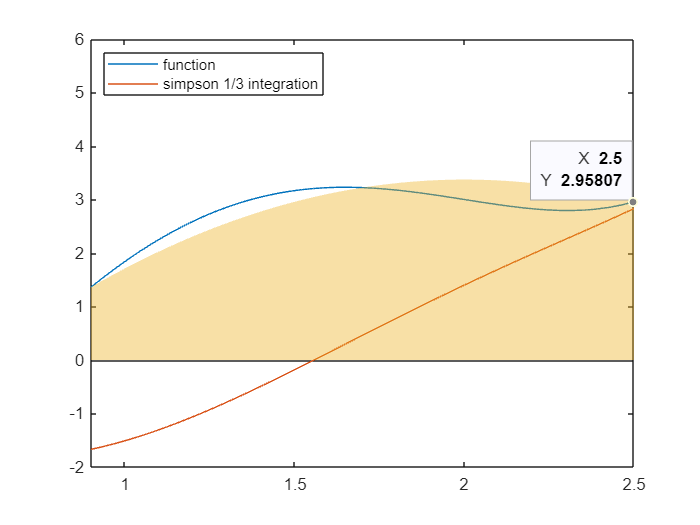

fplot(f)
hold on 
fplot(actual_int)
legend({'function','analytical integral of function'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])

xes=[x_l; x_l+h; x_l+2*h];
fs=double( [f(x_l); f(x_l+h); f(x_l+2*h)] );

sim13_curve=fit( xes, fs, 'poly2');
area( x_c, sim13_curve(x_c), "FaceAlpha", 0.4, "LineStyle","none" )

legend({'function','simpson 1/3 integration'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])

hold off

## Simpson 3/8 method:

### Part1: Numeric Integral calulation

The Trapezoidal integral derived using the following equation:


$$\int_{x_1 }^{x_2 } f\left(x\right)\ldotp \mathrm{dx}=\frac{h}{3}\ldotp \left(f_0 +3f_1 +3f_2 +f_4 \right)$$


h=(x_u-x_l) /3; %integration interval
sim38_int=double( f(x_l) + 3*f(x_l+h) + 3*f(x_l+2*h) + f(x_l+3*h) ) *3*h/8;
disp('4 Point simpson 3/8 integration answer is: '), disp(sim38_int)

4 Point simpson 3/8 integration answer is: 
    4.5404



disp(['ERROR= ', num2str( sim38_int-actual_int_val ) ] )

ERROR= 0.039296


### Part2: Visualization

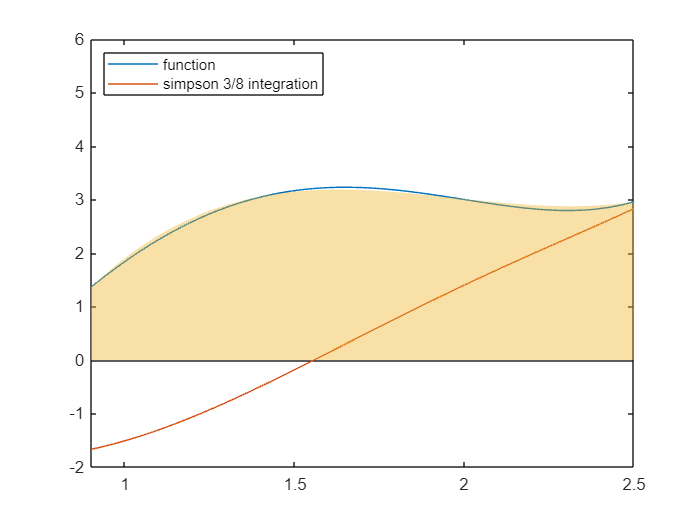

figure
fplot(f)
hold on 
fplot(actual_int)
legend({'function','analytical integral of function'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])

xes=[x_l; x_l+h; x_l+2*h; x_l+3*h];
fs=double( [f(x_l); f(x_l+h); f(x_l+2*h); f(x_l+3*h)] );

sim38_curve=fit( xes, fs, 'poly3');
area( x_c, sim38_curve(x_c), "FaceAlpha", 0.4, "LineStyle","none" )
legend({'function','simpson 3/8 integration'},'Location','northwest')
xlim([x_l x_u])
ylim([-2 6])